# Animation Using Graphic Handles, Reading and Writing Video Files

## Animating polynomial roots as a function of a parameter.

Let $p(x)$ be a polynomial whose coefficients depend on a parameter $t$.


$$p(x) = x^3 - x^2 + \cos(\sqrt{t})x + \sin(t) + \sin(\sqrt{3}t)$$


Make an anonymous function that returns the coefficients of $p(x)$.

p = @(t) [1, -1, cos(sqrt(t)), sin(t) + sin(sqrt(3)*t)];

Find the roots for t = 0 and plot them, save a handle to the plot in `h`, and set the axis limits.

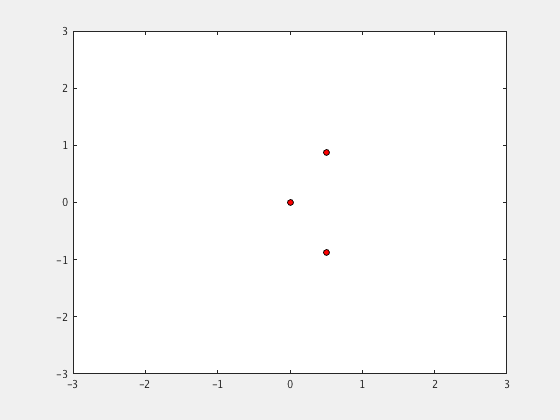

t = 0;
r = roots(p(t));
fh = figure('visible','on'); % A handle to the figure
h = plot(real(r), imag(r), 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 6,...
	'MarkerEdgeColor', 'k');
axis([-3 3 -3 3])

Since we are going to plot the roots in a `while`-loop, we need an exit criterion. We will arrange things so, that when the user clicks anywhere in the figure window, we exit the loop. To achieve this we store a boolean value, initially true, in the `UserData` property of the figure and set the `WindowButtonDownFcn` property to a function handle to the **callback** function `@(hObject, event) set(hObject, 'UserData', false)`, which sets the `UserData` property to false. Here `hObject` is a handle to the figure. We don't need to worry about the other argument for now..

fh.UserData = true;
fh.WindowButtonDownFcn = @(hObject, event) set(hObject, 'UserData', false);

Next we enter the animation loop, where we compute the new roots, use the handle `h` to the plot to replace `XData` and `YData` with new values, and call `drawnow` to update the plot. This is much faster than calling `plot` inside the loop. At the top of the loop we test the value stored in `UserData`. It remains true until the user clicks inside the figure window. Then the callback-function is executed and it sets `UserData` to false, at which time we exit the loop.

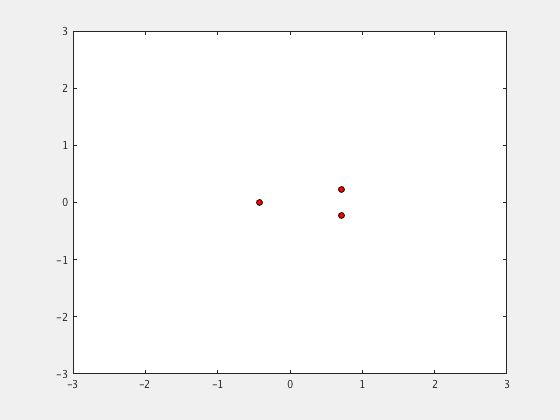

dt = 0.005; %If the animation runs too slow, increase dt.
t = t + dt;
while fh.UserData
    r = roots(p(t));
    h.XData = real(r);
    h.YData = imag(r);
    drawnow
    t = t + dt;
end

## A chaotic attractor

The next example shows how to do animation where the new data doesn't replace the old data. We plot points of the chaotic **Gingerbreadman** map:


$$x(k+1) = 1 - y(k) + |x(k)|$$



$$y(k+1) = x(k)$$


We add a Start/Stop button to the lower left corner of the window. When the user clicks the button the animation starts and the button text changes to `Stop`. When the user clicks the Stop-button the animation stops and the text changes to `Start`. We keep track of the animation state in the `UserData` property of the button. See the callback function `startbuttonCallback` below.

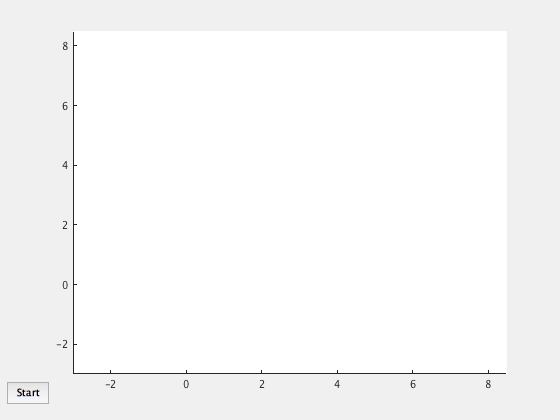

clf
axis([-3 8.5 -3 8.5])
uicontrol('Style', 'pushbutton', 'Units', 'char', 'Position', [1 1 6 1.5],...
    'UserData', false, 'String', 'Start', 'Callback', @startbuttonCallback)

function startbuttonCallback(hObject, ~) % Don't need the second argument
% A callback for the Start/Stop button.

if hObject.UserData
    % Animation is currently running. Setting UserData to false stops it.
    hObject.UserData = false;
else
    % Animation is not running, so we start it and change the button text to
    % 'Stop'.
    hObject.UserData = true;
    hObject.String = 'Stop';
    
    cla % Clear the axes
    
    % Create an animatedline object with initial point (4, 1.9) and
    % set h to a handle to it.
    xo = 4; yo = 1.9;
    h = animatedline(xo, yo, 'LineStyle', 'none', 'Marker', '.',...
        'MarkerSize', 1, 'MaximumNumPoints', Inf, 'Color', [0.65, 0.45, 0.25]);

    % The animation loop continues until UserData becomes false when the user
    % clicks the button.
    % We add new points to the plot with the function addpoints.
    while hObject.UserData
        x = 1 - yo + abs(xo);
        y = xo;
        addpoints(h, x, y);
        drawnow
        xo = x; yo = y;
    end
    hObject.String = 'Start'; % Restore the button text to 'Start'
end
end